# ECMOR-2022

## Introduction

bound = [0,1];

genK = @(N) genField(N+1, 1e-4, 1e-3, 0.1, 0.4); % non-uniform

calcG = @(u) [1 + 0.5 * u.^2, u];

genBC_val = @(N) genField(N+2, 0, 10,0.1, 0.1); % initial and boundary

gen_q_pos = @(k) (-4)^(k) * (rand()-0.5)^(2*k+1)+0.5;

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 1e-9,...
    'tol_rel'  , 1e-9,...
    'tol_g'    , 1e-4,...
    'tol_rel_g', 1e-4 ...
    );

nlin_newton = @(x,Res,Jac) newton(x,Res,Jac,newton_param);

### FOM

 
Nx = 250;
dx = 1/Nx;

K = genK(Nx);
q_pos = gen_q_pos(1);
q_val = 2;
U0 = genBC_val(Nx);
x0 = U0(2:end-1);

D.val = K; D.model = calcG;

BC = genBC(1,[U0(1),U0(end)]);

Q.pos = round(Nx*q_pos); Q.val = sparse(Q.pos,1,q_val,Nx,1);

param = genParam(D,BC,Q);

makeFOM = @(name) genProblem(name,Nx,param,x0);
makeROM_I = @(name, encoder) genProblem(name,Nx,param,x0,encoder);

FOM = makeFOM('FOM');

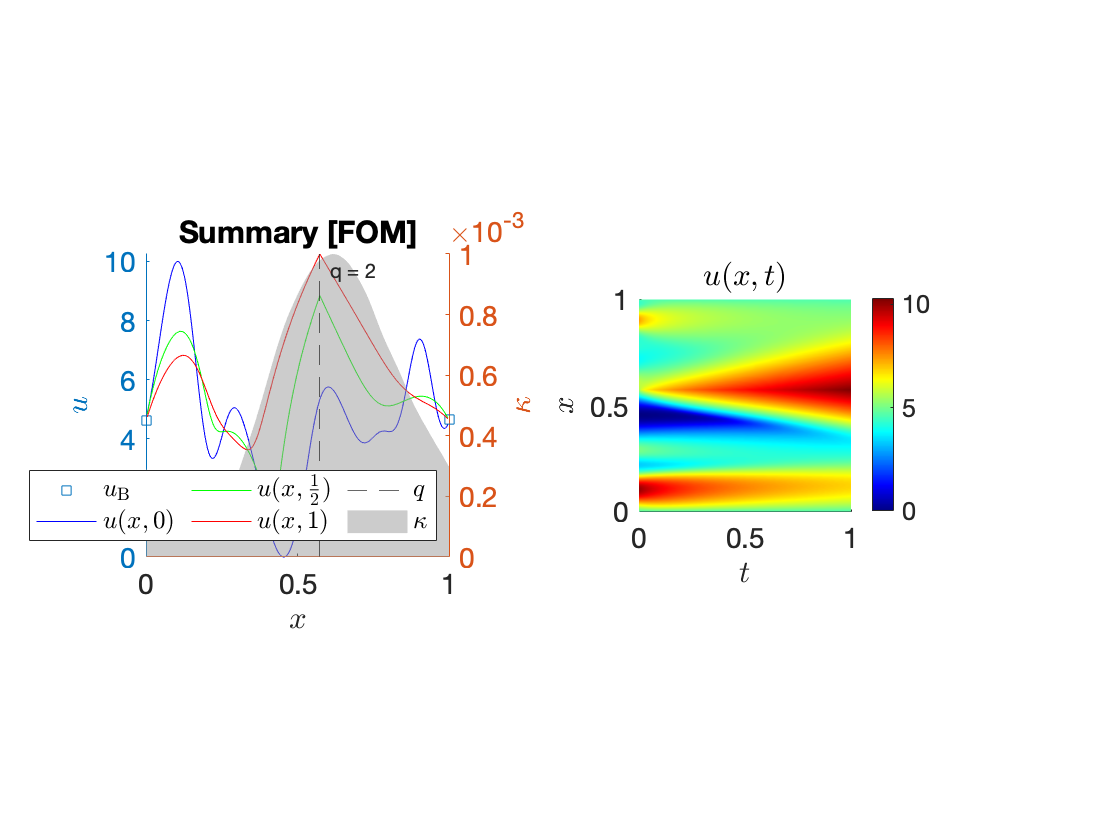

Nt = 100;
FOM = solveDif(1,Nt,FOM, nlin_newton);
plotSol(figure(),FOM,14);

### ROM-I

#### PCA

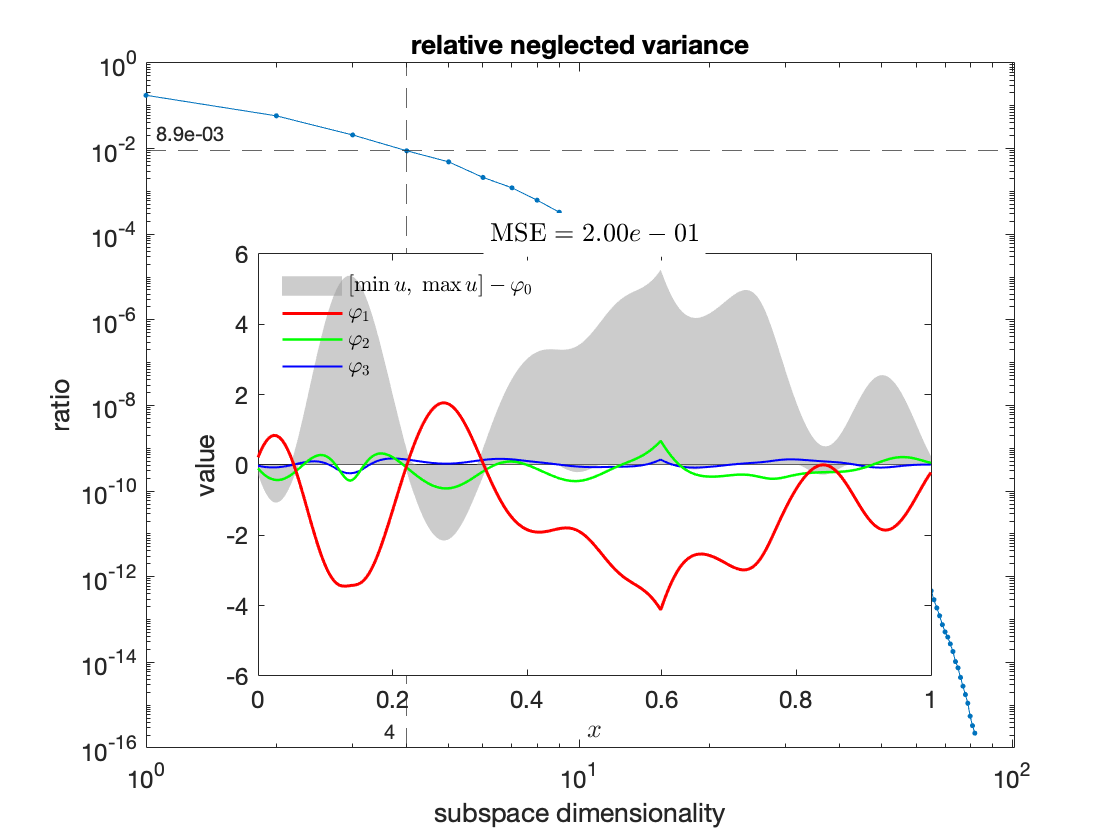

POD = PCA(FOM.X, 1e-2, 'init', FOM.X(:,1)).plotSummary(figure(),'FontSize',12, 'layout','built-in');

#### Simulation

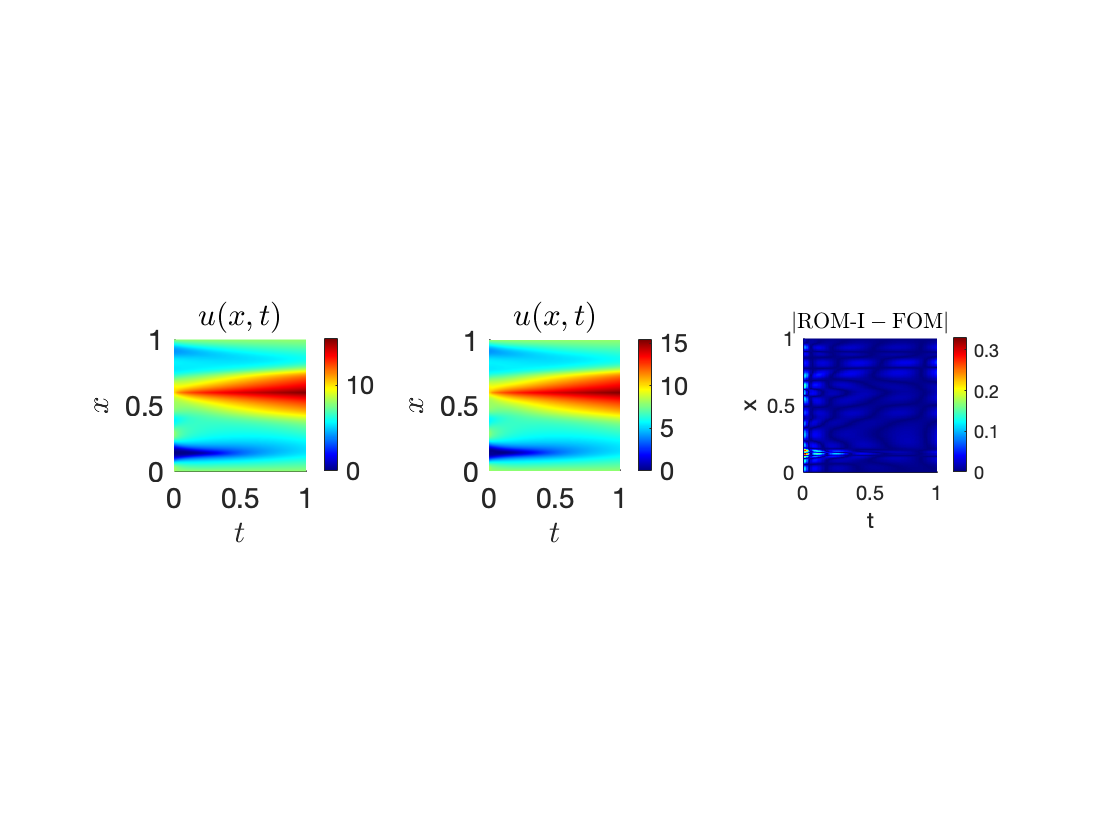


ROM_I = makeROM_I('ROM-I', POD.genEncoder());
nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param, POD.genEncoder().decjac);

ROM_I = solveDif(1,Nt,ROM_I,nlin.gauss);
ROM_I.X = POD.decode(ROM_I.X);
plotComp(figure(),FOM,ROM_I);

### ROM-II

### Generalizing ability

#### High

#### Low

## Method 1

### POD basis for different x_q

### Domain decomposition and mapping

### Zero-order approach

### Domain-wise POD performance